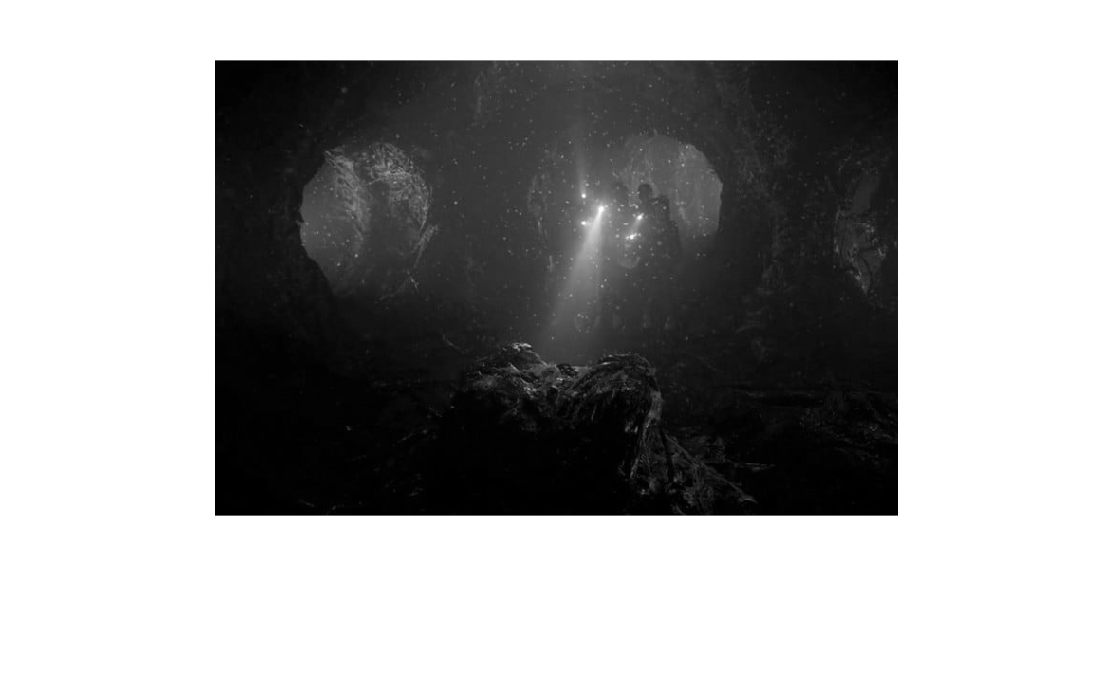

%EXERCICI 1a
x = im2gray(im2double(imread('Stranger.jpg')));
imshow(x);

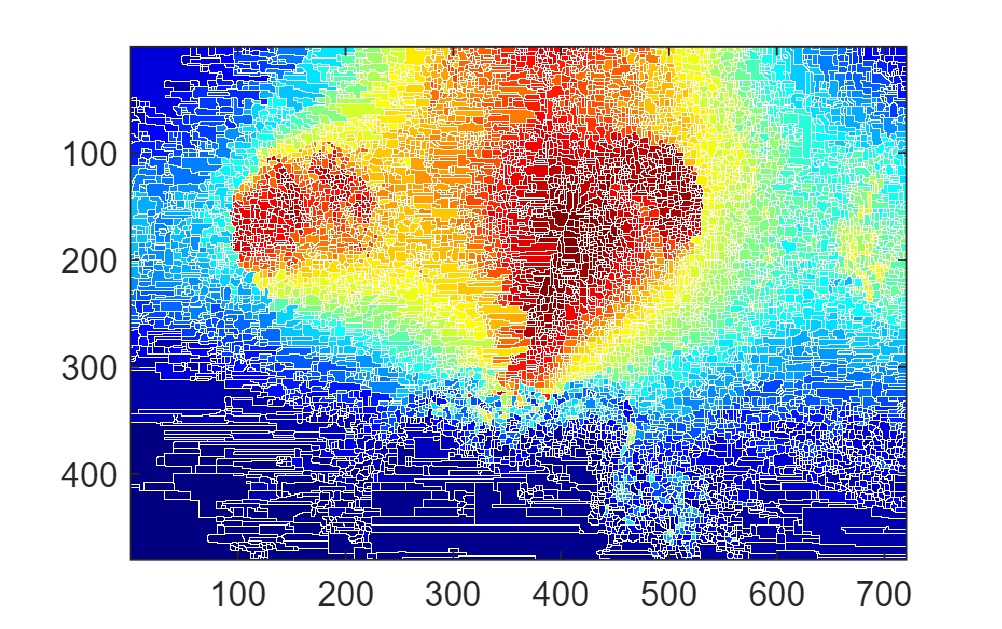


%Fem el watersheed
y = watershed2(x*255,8);

%Convertim la imatge a RGB 
color_map = im2double(label2rgb(y));
imagesc(color_map);

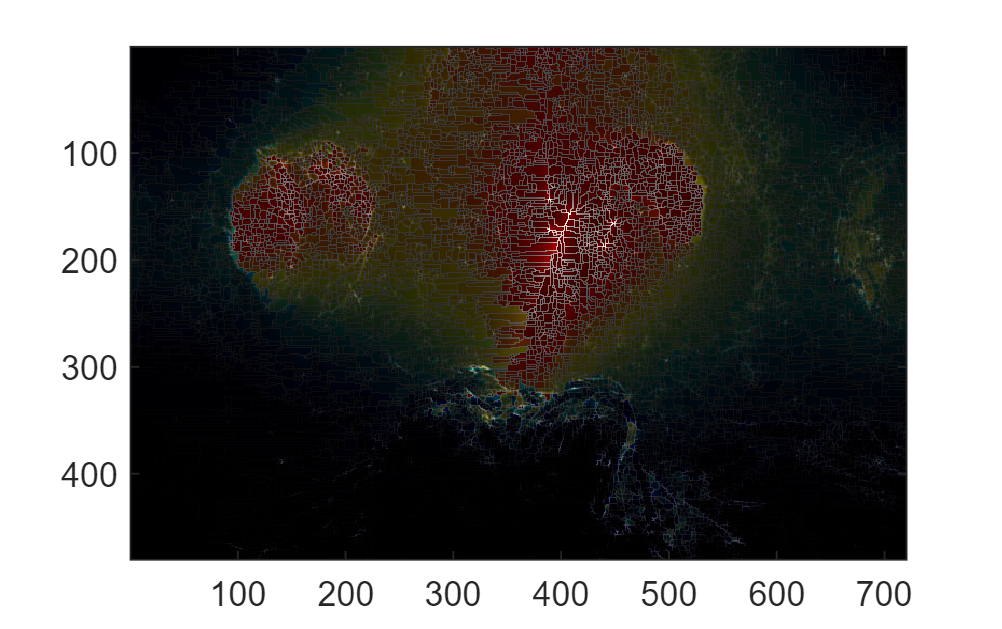


%Separem els tres canals 
canalR = color_map(:,:,1);
canalG = color_map(:,:,2);
canalB = color_map(:,:,3);

%Multipliquem cada canal per la imatge
x_R = canalR.*x;
x_G = canalG.*x;
x_B = canalB.*x;

%Concatenem les tres imatges i fem plot del resultat final
x_final = cat(3, x_R, x_G, x_B);
imagesc(x_final);

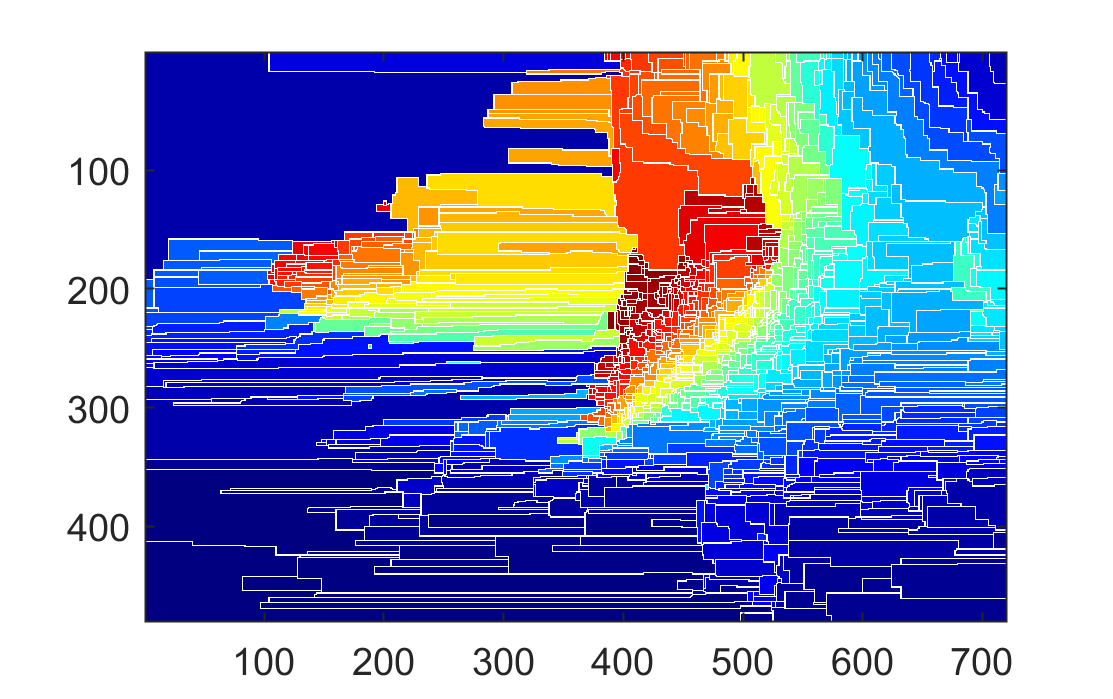



%EXERCICI 1b
x = im2gray(im2double(imread('Stranger.jpg')));

%ELEMENT ESTRUCTURAL (10,10)
se = ones(10,10);

%Apliquem el filtre morfològic
opening = imdilate(imerode(x,se),se);
closing = imerode(imdilate(opening,se),se);

%Fem el watersheed
y = watershed2(closing*255,8);

color_map = im2double(label2rgb(y));
imagesc(color_map);

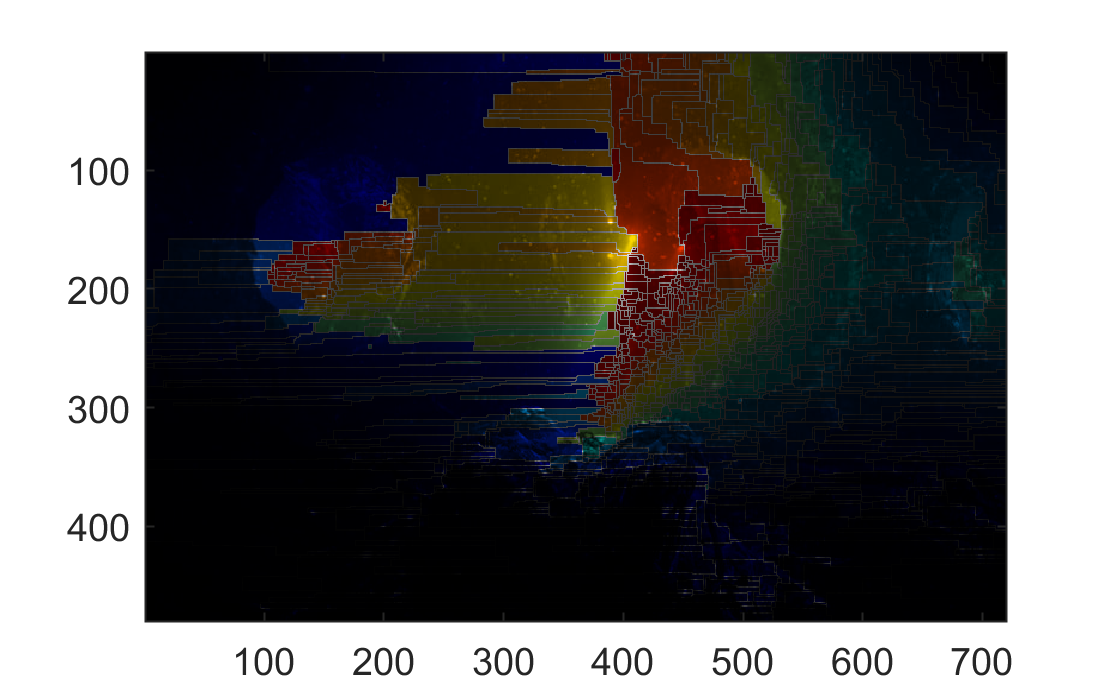

 
canalR = color_map(:,:,1);
canalG = color_map(:,:,2);
canalB = color_map(:,:,3);

x_R = canalR.*x;
x_G = canalG.*x;
x_B = canalB.*x;

x_final = cat(3, x_R, x_G, x_B);
imagesc(x_final);

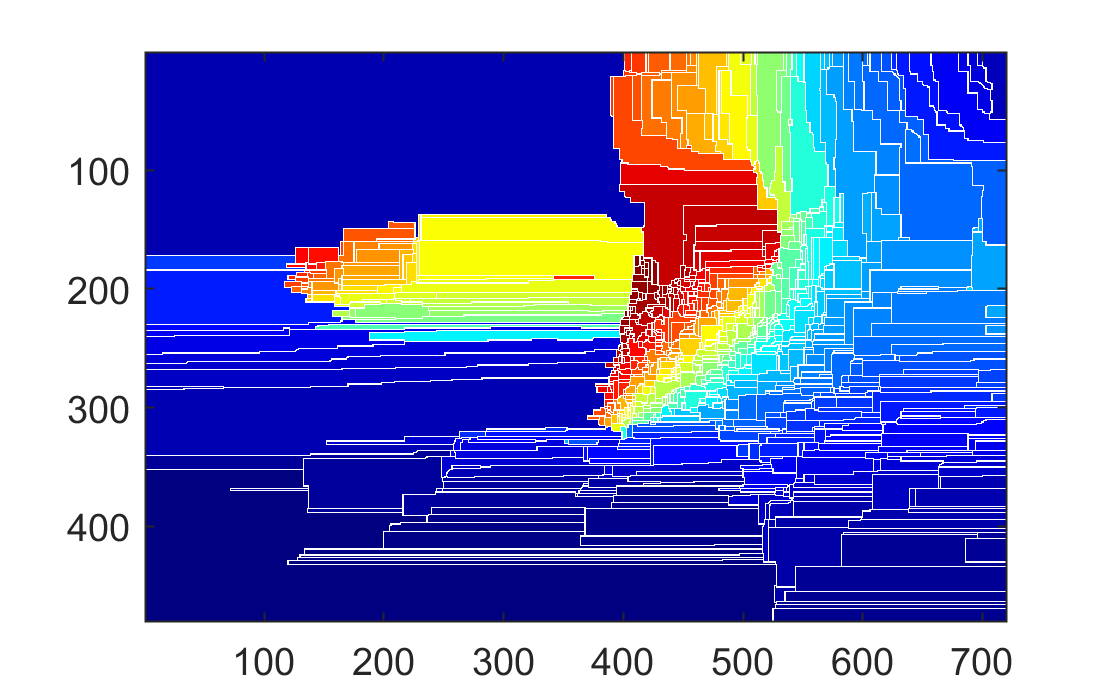


%ELEMENT ESTRUCTURAL (20,20)
se = ones(20,20);

%Apliquem el filtre morfològic
opening = imdilate(imerode(x,se),se);
closing = imerode(imdilate(opening,se),se);

%Fem el watersheed
y = watershed2(closing*255,8);

color_map = im2double(label2rgb(y));
imagesc(color_map);

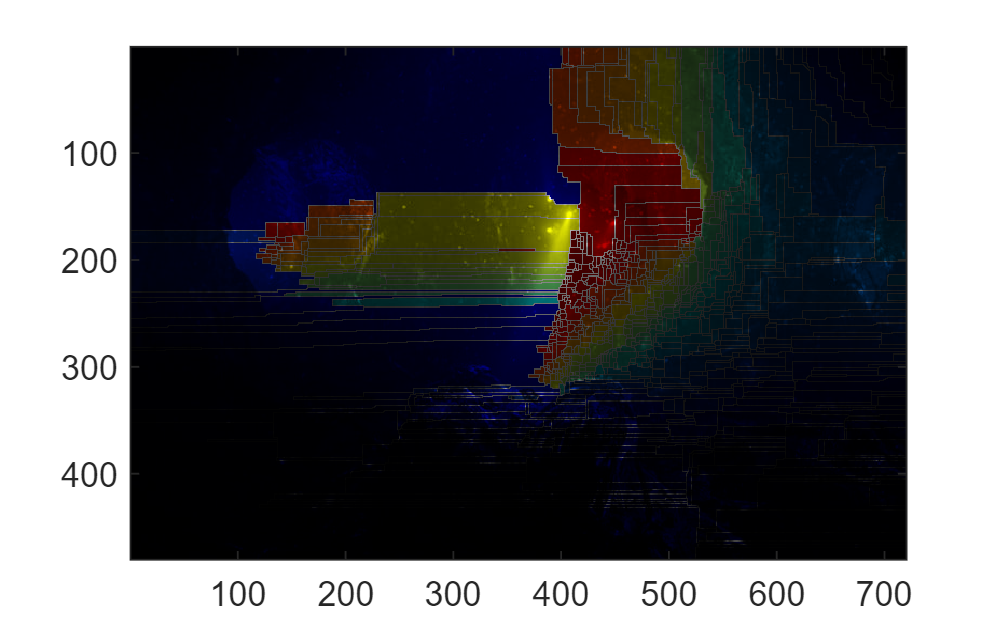

 
canalR = color_map(:,:,1);
canalG = color_map(:,:,2);
canalB = color_map(:,:,3);

x_R = canalR.*x;
x_G = canalG.*x;
x_B = canalB.*x;

x_final = cat(3, x_R, x_G, x_B);
imagesc(x_final);